clear all;
close all;

clock_freq = 1e8;
limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 22, 24, 26, 28, 30, 35, 45, 60, 75, 100, 125, 150, 175, 200];

## RO-PUF

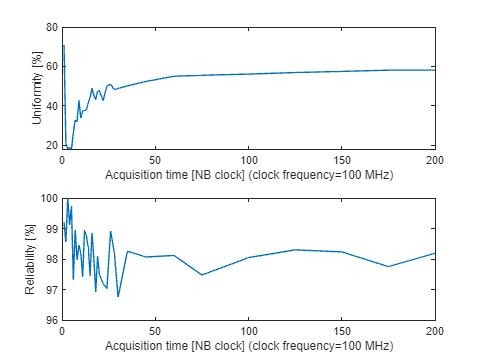

prefix = "ro_raw";

uniformities_ro = zeros(1, length(limits));
reliabilities_ro = zeros(1, length(limits));

data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_ro, size_response_ro] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    [~, ~, ~, uniformities_ro(i), reliabilities_ro(i), ~, ~] = intra_device_analysis_fn(data);
end

figure;
subplot(2,1,1);
subtitle(string(size_sample_ro));
plot(limits, uniformities_ro);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Uniformity [%]");

subplot(2,1,2);
plot(limits, reliabilities_ro);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Reliability [%]");

## TERO-4-PUF

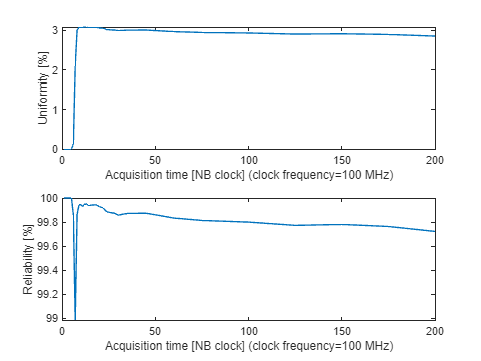

prefix = "tero_4_raw";

uniformities_tero_4 = zeros(1, length(limits));
reliabilities_tero_4 = zeros(1, length(limits));

data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_tero_4, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    [~, ~, ~, uniformities_tero_4(i), reliabilities_tero_4(i), ~, ~] = intra_device_analysis_fn(data);
end

figure;
subplot(2,1,1);
subtitle(string(size_sample_tero_4));
plot(limits, uniformities_tero_4);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Uniformity [%]");

subplot(2,1,2);
plot(limits, reliabilities_tero_4);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Reliability [%]");

## TERO-8-PUF

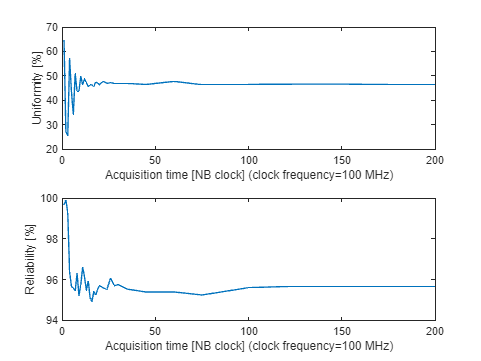

prefix = "tero_8_raw";

uniformities_tero_8 = zeros(1, length(limits));
reliabilities_tero_8 = zeros(1, length(limits));

data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_tero_8, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    [~, ~, ~, uniformities_tero_8(i), reliabilities_tero_8(i), ~, ~] = intra_device_analysis_fn(data);
end

figure;
subplot(2,1,1);
subtitle(string(size_sample_tero_8));
plot(limits, uniformities_tero_8);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Uniformity [%]");

subplot(2,1,2);
plot(limits, reliabilities_tero_8);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Reliability [%]");

## RO vs TERO-8

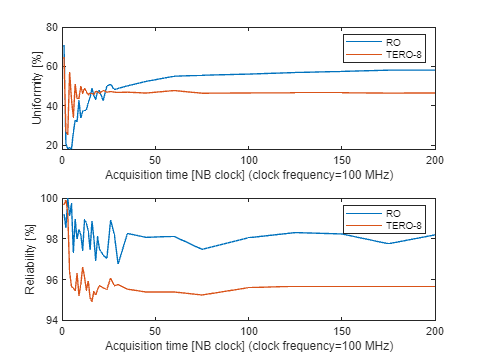

figure;
subplot(2,1,1);
plot(limits, uniformities_ro);
hold on;
plot(limits, uniformities_tero_8);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Uniformity [%]");
legend("RO","TERO-8")

subplot(2,1,2);
plot(limits, reliabilities_ro);
hold on;
plot(limits, reliabilities_tero_8);
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Reliability [%]");
legend("RO","TERO-8")